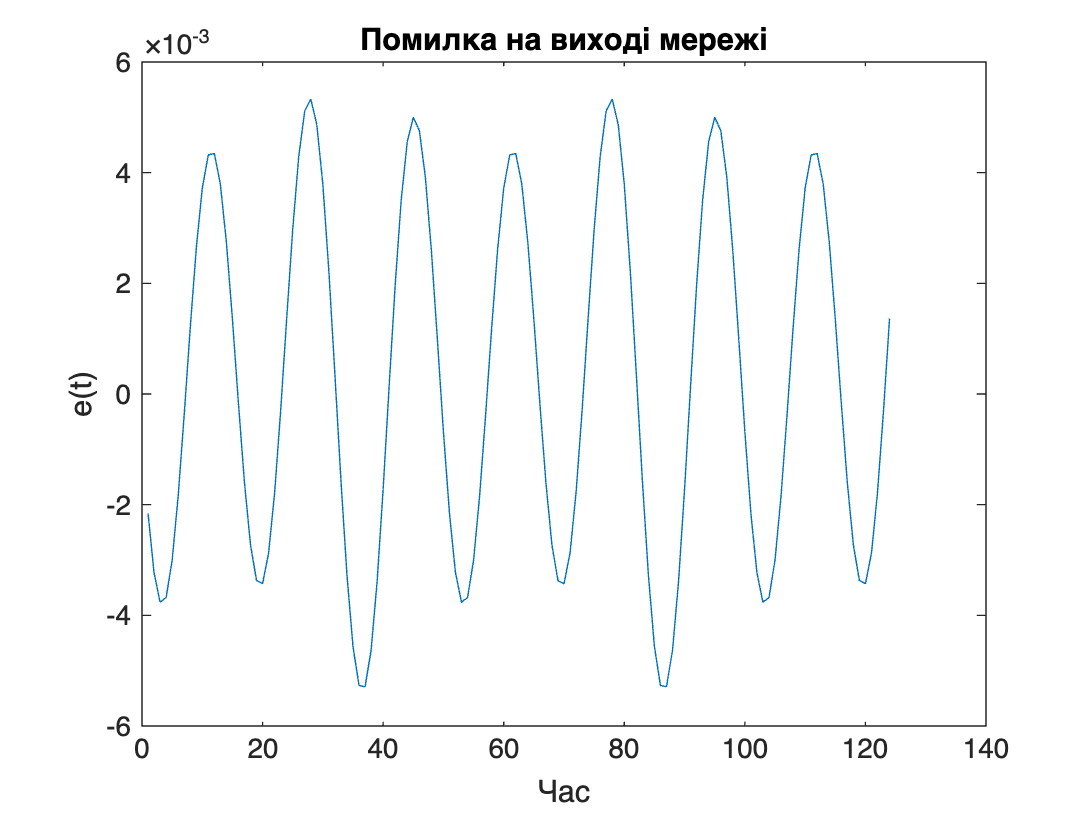

Fs = 50;                     % Частота дискретизації
t = 0:1/Fs:2.5;              % Часовий вектор
x = sin(2*pi*t);             % Вхідна функція x(t)
y = 2 * x + 3;
x_seq = con2seq(x);
y_seq = con2seq(y);

net = timedelaynet(1:2, 1);  % 2 затримки
[Xs, Xi, Ai, Ts] = preparets(net, x_seq, y_seq);

net.trainParam.epochs = 1000;
net.trainParam.goal = 1e-5;
net = train(net, Xs, Ts, Xi, Ai);

Y = net(Xs, Xi);
perf = perform(net, Ts, Y);
e = gsubtract(Ts, Y);
figure;
plot(cell2mat(e));
title('Помилка на виході мережі');
xlabel('Час');
ylabel('e(t)');

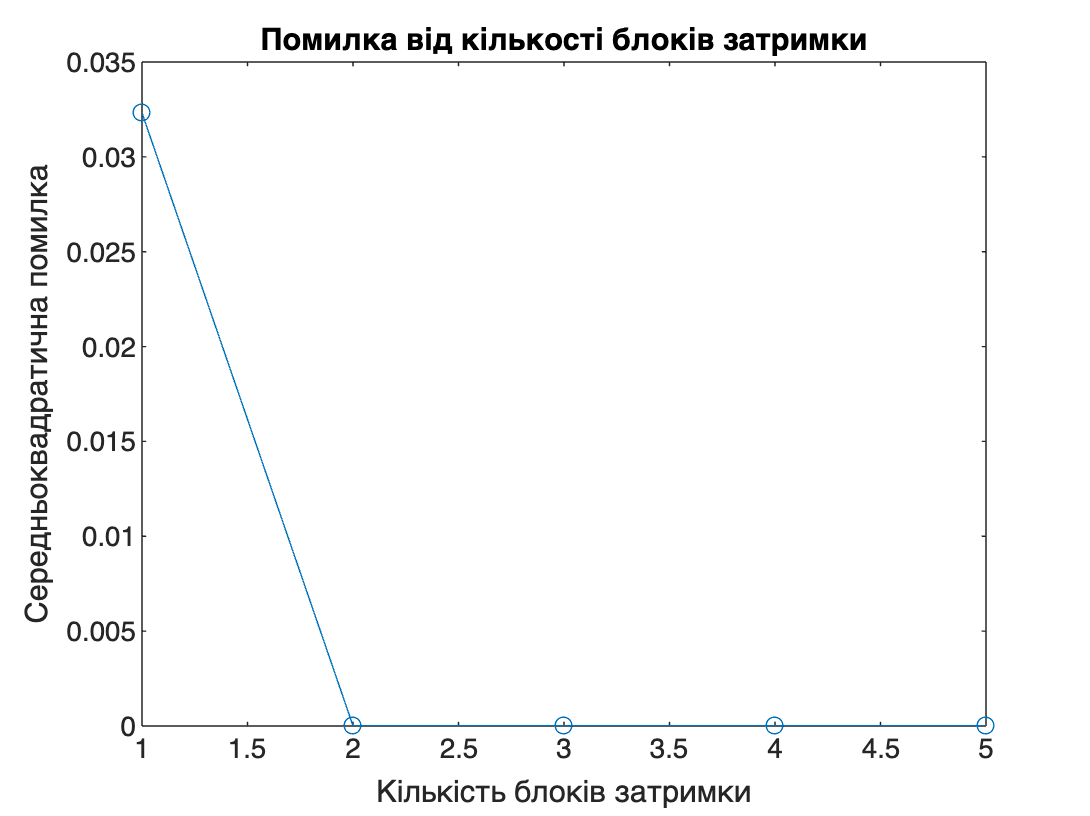


max_delays = 5;
errors = zeros(1, max_delays);

for d = 1:max_delays
    net = timedelaynet(1:d, 1);
    [Xs, Xi, Ai, Ts] = preparets(net, x_seq, y_seq);
    net.trainParam.epochs = 1000;
    net.trainParam.goal = 1e-5;
    net = train(net, Xs, Ts, Xi, Ai);
    Y = net(Xs, Xi);
    errors(d) = perform(net, Ts, Y);
end

figure;
plot(1:max_delays, errors, '-o');
xlabel('Кількість блоків затримки');
ylabel('Середньоквадратична помилка');
title('Помилка від кількості блоків затримки');